`Erfan Panahi ``810103084`

# `Introduction to Statistical Inference`

## `Homework #02 - ``Problem 6`

clc
clear
close all

- `Part 1, 2.`

ITR = 1e5;
N = [10, 25, 100, 1000];
Sn = zeros(4, ITR);
for i = 1:ITR
    Sn(1, i) = Roulette(N(1));
    Sn(2, i) = Roulette(N(2));
    Sn(3, i) = Roulette(N(3));
    Sn(4, i) = Roulette(N(4));
end
figure
subplot(2, 2, 1)
histogram(Sn(1, :));
xline(mean(Sn(1, :)), 'LineStyle', '--', 'Color', 'r', 'LineWidth', 2)
xline(std(Sn(1, :)) + mean(Sn(1, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
xline(-std(Sn(1, :)) + mean(Sn(1, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
legend('Distribution', 'Expected Value', 'Standard Deviation', 'Interpreter', 'latex')
title('Distribution of total earnings for $N=10$', 'Interpreter','latex')
subplot(2, 2, 2)
histogram(Sn(2, :));
xline(mean(Sn(2, :)), 'LineStyle', '--', 'Color', 'r', 'LineWidth', 2)
xline(std(Sn(2, :)) + mean(Sn(2, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
xline(-std(Sn(2, :)) + mean(Sn(2, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
legend('Distribution', 'Expected Value', 'Standard Deviation', 'Interpreter', 'latex')
title('Distribution of total earnings for $N=25$', 'Interpreter','latex')
subplot(2, 2, 3)
histogram(Sn(3, :));
xline(mean(Sn(3, :)), 'LineStyle', '--', 'Color', 'r', 'LineWidth', 2)
xline(std(Sn(3, :)) + mean(Sn(3, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
xline(-std(Sn(3, :)) + mean(Sn(3, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
legend('Distribution', 'Expected Value', 'Standard Deviation', 'Interpreter', 'latex')
title('Distribution of total earnings for $N=100$', 'Interpreter','latex')
subplot(2, 2, 4)
histogram(Sn(4, :));
xline(mean(Sn(4, :)), 'LineStyle', '--', 'Color', 'r', 'LineWidth', 2)
xline(std(Sn(4, :)) + mean(Sn(4, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
xline(-std(Sn(4, :)) + mean(Sn(4, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
legend('Distribution', 'Expected Value', 'Standard Deviation', 'Interpreter', 'latex')
title('Distribution of total earnings for $N=1000$', 'Interpreter','latex')

`Part 3.`

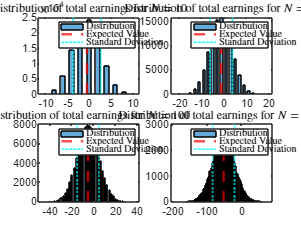

SnN = Sn ./ N.';
figure
subplot(2, 2, 1)
histogram(SnN(1, :));
xline(mean(SnN(1, :)), 'LineStyle', '--', 'Color', 'r', 'LineWidth', 2)
xline(std(SnN(1, :)) + mean(SnN(1, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
xline(-std(SnN(1, :)) + mean(SnN(1, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
legend('Distribution', 'Expected Value', 'Standard Deviation', 'Interpreter', 'latex')
title('Distribution of average winnings for $N=10$', 'Interpreter','latex')
subplot(2, 2, 2)
histogram(SnN(2, :));
xline(mean(SnN(2, :)), 'LineStyle', '--', 'Color', 'r', 'LineWidth', 2)
xline(std(SnN(2, :)) + mean(SnN(2, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
xline(-std(SnN(2, :)) + mean(SnN(2, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
legend('Distribution', 'Expected Value', 'Standard Deviation', 'Interpreter', 'latex')
title('Distribution of average winnings for $N=25$', 'Interpreter','latex')
subplot(2, 2, 3)
histogram(SnN(3, :));
xline(mean(SnN(3, :)), 'LineStyle', '--', 'Color', 'r', 'LineWidth', 2)
xline(std(SnN(3, :)) + mean(SnN(3, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
xline(-std(SnN(3, :)) + mean(SnN(3, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
legend('Distribution', 'Expected Value', 'Standard Deviation', 'Interpreter', 'latex')
title('Distribution of average winnings for $N=100$', 'Interpreter','latex')
subplot(2, 2, 4)
histogram(SnN(4, :));
xline(mean(SnN(4, :)), 'LineStyle', '--', 'Color', 'r', 'LineWidth', 2)
xline(std(SnN(4, :)) + mean(SnN(4, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
xline(-std(SnN(4, :)) + mean(SnN(4, :)), 'LineStyle', ':', 'Color', 'c', 'LineWidth', 1.5)
legend('Distribution', 'Expected Value', 'Standard Deviation', 'Interpreter', 'latex')
title('Distribution of average winnings for $N=1000$', 'Interpreter','latex')

`Part 4.`

fprintf("N = 10:\t\t E[Sn] = %f, \t sigma_N = %f", mean(Sn(1, :)), std(Sn(1, :)));

N = 10:		 E[Sn] = -0.531280, 	 sigma_N = 3.170464

fprintf("N = 25:\t\t E[Sn] = %f, \t sigma_N = %f", mean(Sn(2, :)), std(Sn(2, :)));

N = 25:		 E[Sn] = -1.301500, 	 sigma_N = 5.006710

fprintf("N = 100:\t E[Sn] = %f, \t sigma_N = %f", mean(Sn(3, :)), std(Sn(3, :)));

N = 100:	 E[Sn] = -5.281440, 	 sigma_N = 9.981140

fprintf("N = 1000:\t E[Sn] = %f, \t sigma_N = %f", mean(Sn(4, :)), std(Sn(4, :)));

N = 1000:	 E[Sn] = -52.666660, 	 sigma_N = 31.437806

`Part 5.`

losing_rate = sum(Sn(2, :) < 0) / ITR

losing_rate = 0.6046

`Part 6.`

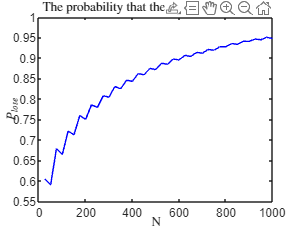

n = 25:25:1000;
losing_rate = zeros(1, length(n));
for i = 1:length(n)
    Sn = zeros(1, ITR);
    for j = 1:ITR
        Sn(j) = Roulette(n(i));
    end
    losing_rate(i) = sum(Sn < 0) / ITR;
end
figure
plot(n, losing_rate, 'b')
title('The probability that the casino loses money', 'Interpreter', 'latex')
xlabel('N', 'Interpreter', 'latex')
ylabel('$P_{lose}$', 'Interpreter', 'latex')

# `Functions.`

function [Sn] = Roulette(N)
    random_num = rand(1, N);
    winning = zeros(1, N);
    winning(random_num <= 9/19) = 1;
    winning(random_num > 9/19) = -1;
    Sn = sum(winning);
end